# Code for Non-Changing Area

Code to sort the objects that will remain at the same position, shape and orientation by hard-coding movements

#### Initial Setup:

addpath('utils')
rosIP = "192.168.56.103"; % Change the IP Address 
rosshutdown; 
rosinit(rosIP,11311);

Initializing global node /matlab_global_node_88655 with NodeURI http://192.168.56.1:58459/ and MasterURI http://192.168.56.103:11311.


setInitialConfig_franka;
physicsClient = rossvcclient('gazebo/unpause_physics');
physicsResp = call(physicsClient,'Timeout',3);
pause(2);
load("yolov2-final-nn-12-4-23.mat","detector");

#### Find Centroids 

currentpos = moveTo(0.4,0,0.4,1,1)

currentpos =     0.4000         0    0.4000    1.0000    1.0000


pause(2);
img = getRgb();
[labelsOG,centroidsOG,nosOG,trackingRegionsOG,boxRegionsOG] = detectObjects(img,detector)

labelsOG = 3×1 categorical array
     bottle_standing 
     bottle 
     can 


centroidsOG =   119.1313  300.5524
  535.5000  332.0000
  349.0000  359.5000


nosOG = 3

trackingRegionsOG =    99.1313  139.1313  280.5524  320.5524
  515.5000  555.5000  312.0000  352.0000
  329.0000  369.0000  339.5000  379.5000


boxRegionsOG =      3     4     4


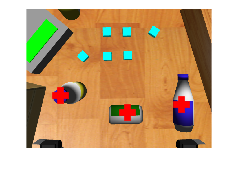

plotPoints(img,centroidsOG)

#### Track First Centroid in a Loop

prevTrackingRegions = trackingRegionsOG;
prevBoxRegions = boxRegionsOG;
trackID = 1

trackID = 1

currentpos =     0.3900    0.0100    0.4000    1.0000    1.0000


labels = 3×1 categorical array
     bottle_standing 
     can 
     bottle 


centroids =   132.2231  282.2730
  352.0000  346.5000
  540.0000  330.5000


nos = 3

trackingRegions =   112.2231  152.2231  262.2730  302.2730
  332.0000  372.0000  326.5000  366.5000
  520.0000  560.0000  310.5000  350.5000


boxRegions =      3     4     4


prevTrackRegion =    99.1313  139.1313  280.5524  320.5524


x = 99.1313

y = 280.5524

xlim = 139.1313

ylim = 320.5524

centx = 132.2231

centy = 282.2730

trackID = 1

trackID = 1

currentpos =     0.3800    0.0200    0.4000    1.0000    1.0000


labels = 3×1 categorical array
     bottle_standing 
     bottle 
     can 


centroids =   145.9557  268.2958
  543.0000  308.5000
  359.5000  339.5000


nos = 3

trackingRegions =   125.9557  165.9557  248.2958  288.2958
  523.0000  563.0000  288.5000  328.5000
  339.5000  379.5000  319.5000  359.5000


boxRegions =      3     4     4


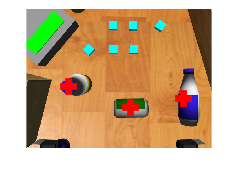

prevTrackRegion =   112.2231  152.2231  262.2730  302.2730


x = 112.2231

y = 262.2730

xlim = 152.2231

ylim = 302.2730

centx = 145.9557

centy = 268.2958

trackID = 1

trackID = 1

if prevBoxRegions(1) ~= 5
    for i = 1:2
        switch prevBoxRegions(trackID)
            case 2
                currentpos = moveBy(currentpos,0.01,-0.01)
            case 1
                currentpos = moveBy(currentpos,0.01,0.01)
            case 4
                currentpos = moveBy(currentpos,-0.01,-0.01)
            case 3
                currentpos = moveBy(currentpos,-0.01,0.01)
            case 5
                break;
        end
        img = getRgb();
        [labels,centroids,nos,trackingRegions,boxRegions] = detectObjects(img,detector)
        plotPoints(img,centroids)
        prevTrackRegion = prevTrackingRegions(trackID,:)
        x = prevTrackRegion(1)
        y = prevTrackRegion(3)
        xlim = prevTrackRegion(2)
        ylim = prevTrackRegion(4)
        for e = 1:nos
            centx = centroids(e,1)
            centy = centroids(e,2)
            if centx >  x && centx < xlim && centy > y && centy < ylim
                trackID = e
                trackID
                break
            end
        end
        prevBoxRegions = boxRegions;
        prevTrackingRegions = trackingRegions;
    end
end

currentpos = [0.4,0,0.4,1,1]

currentpos =     0.4000         0    0.4000    1.0000    1.0000


currrentpos = moveTo(currentpos(1),currentpos(2),0.05,1,2)

currrentpos =     0.4000         0    0.0500    1.0000    2.0000


pause(2)
grip(4,100)
pause(2)
currrentpos = moveTo(currentpos(1),currentpos(2),-0.2,1,2)

currrentpos =     0.4000         0   -0.2000    1.0000    2.0000


pause(2)
grip(0,100)